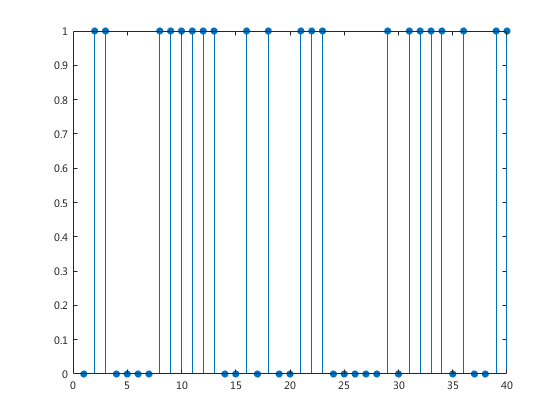

% define constant
M=16;
EbNo = 10;
N=3e4;

% generate N test data of range M
x = randi([0,1],N,1);

k = log2(M);
nsamp = 1;

xx = bi2de(reshape(x,k,length(x)/k).','left-msb');

% define noise
snr = EbNo +10*log10(k) - 10*log10(nsamp);

% plot data samples
figure;
stem(x(1:40),'filled');

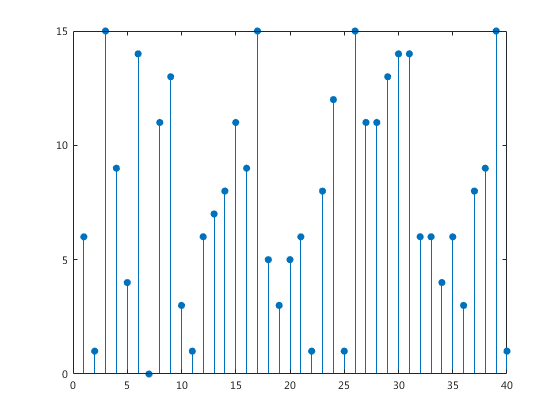

figure;
stem(xx(1:40),'filled');

% modulation
tx = qammod(xx, M,'Gray');

% generate rx signal via channel
rx = awgn(tx, snr,'measured');

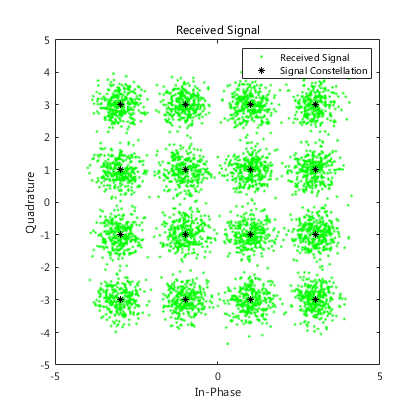

% draw scatterplot
figure;
hh = scatterplot(rx(1:nsamp*5e3),nsamp,0,'g.');
hold on;
scatterplot(tx(1:5e3),1,0,'k*',hh);
title('Received Signal');
legend('Received Signal','Signal Constellation');
axis([-5 5 -5 5]);
hold off;

% demodulation
rx_demod = qamdemod( rx, M, 'Gray' );

% convert rx signal
y = de2bi(rx_demod,'left-msb');
y = reshape(y.',numel(y),1);

% calculate bit error
[num_err,err] = biterr(xx,rx_demod);

disp(num_err);

    54



disp(err);

    0.0018

